%% PlutoSDR Configuration

fs = 20e6;
centerFrequencyHz = 2.470e9;

samplesPerFrame = 2^14;
numFrames = 64;

nfft = 2^18;

%% Initialize PlutoSDR Receiver

rx = sdrrx('Pluto', ...
    'CenterFrequency', centerFrequencyHz, ...
    'BasebandSampleRate', fs, ...
    'SamplesPerFrame', samplesPerFrame, ...
    'OutputDataType', 'double', ...
    'GainSource', 'AGC Slow Attack');

cleanup = onCleanup(@() release(rx));

%% Capture Samples

samples = complex(zeros(samplesPerFrame * numFrames, 1));

for k = 1:numFrames

    samples((k-1)*samplesPerFrame + (1:samplesPerFrame)) = rx();

end

## Establishing connection to hardware. This process can take several seconds.



fprintf('Captured %d samples.\n', numel(samples));

Captured 1048576 samples.


%% Process Signal

samples = samples - mean(samples);

window = hann(samplesPerFrame);

numSegments = floor(numel(samples) / samplesPerFrame);

x = reshape(samples(1:numSegments*samplesPerFrame), ...
    samplesPerFrame, []);

x = x .* window;

spectrum = fftshift(fft(x, nfft, 1), 1);

power = mean(abs(spectrum).^2, 2);

powerDb = 10*log10(power + eps);

frequencyHz = centerFrequencyHz + ...
    (-nfft/2:nfft/2-1).' * fs/nfft;

%% Find Strongest Frequency

[detectedPowerDb, index] = max(powerDb);

detectedFrequencyHz = frequencyHz(index);

fprintf('Strongest Frequency: %.6f MHz\n', ...
    detectedFrequencyHz / 1e6);

Strongest Frequency: 2464.841156 MHz



fprintf('Strongest Power: %.2f dB\n', ...
    detectedPowerDb);

Strongest Power: 54.70 dB


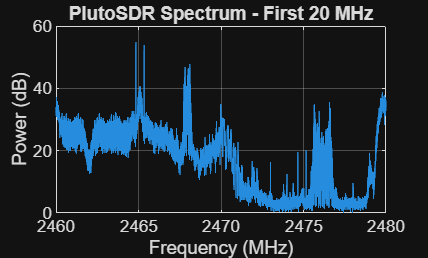

%% Plot Captured Spectrum

figure;

plot(frequencyHz / 1e6, powerDb);

xlabel('Frequency (MHz)');
ylabel('Power (dB)');

title('PlutoSDR Spectrum - First 20 MHz');

grid on;